%HW 7

clear;


syms s;

Gs = (1350*(s+2)*(s+10)*(s+32))/(s*(s+4)*(s^2+8*s+32));
Ts = simplify(Gs/(1+Gs));

[num,den] = numden(Ts);

roots(sym2poly(den));

Rs = 32/s^3

$$Rs = \frac{32}{s^{3}}$$

Es = simplify(Rs / (1+Gs))

$$Es = \frac{32\,\left(s^{3}+12\,s^{2}+64\,s+128\right)}{s^{2}\,\left(s^{4}+1362\,s^{3}+59464\,s^{2}+545528\,s+864000\right)}$$

limEs = s*Es

$$limEs = \frac{32\,\left(s^{3}+12\,s^{2}+64\,s+128\right)}{s\,\left(s^{4}+1362\,s^{3}+59464\,s^{2}+545528\,s+864000\right)}$$

error = subs(limEs, 0)

Error using sym/subs (line 156)
Division by zero.

vpa(error)

%HW 7_2
clear;


syms s K;

Gs = K/(s*(s+3));
Hs = 9*s/K

$$Hs = \frac{9\,s}{K}$$

Ges = simplify(Gs/(1+Gs*Hs));



Rs = 50/s^2

$$Rs = \frac{50}{s^{2}}$$

Es = simplify(Rs / (1+Ges))

$$Es = \frac{50\,\left(s+12\right)}{s\,\left(s^{2}+12\,s+K\right)}$$

limEs = s*Es

$$limEs = \frac{50\,\left(s+12\right)}{s^{2}+12\,s+K}$$

error = subs(limEs,s = 0)

$$error = \frac{600}{K}$$

vpa(error)

$$ans = \frac{600.0}{K}$$

%HW7_3


clear;


syms s K Ds Rs;

% these dont change
G1 = 5

G1 = 5

G2 = 7/(s+2)

$$G2 = \frac{7}{s+2}$$


Es = (1 / (1 + G1*G2)) * Rs - (G2/ (1 + G1*G2)) * Ds;

% substitute new values for a, b, and c
Es = subs(Es,{Rs,Ds},{3/s,-1/s})

$$Es = \frac{3}{s\,\left(\frac{35}{s+2}+1\right)}+\frac{7}{s\,\left(s+2\right)\,\left(\frac{35}{s+2}+1\right)}$$


limEs = s*Es

$$limEs = s\,\left(\frac{3}{s\,\left(\frac{35}{s+2}+1\right)}+\frac{7}{s\,\left(s+2\right)\,\left(\frac{35}{s+2}+1\right)}\right)$$


limEs= simplify(limEs)

$$limEs = \frac{3\,s+13}{s+37}$$

einf= subs(limEs,s,0)

$$einf = \frac{13}{37}$$



vpa(einf)

$$ans = 0.35135135135135135135135135135135$$

%HW7_4
clear;

syms s
Hos = s+1

$$Hos = s+1$$

Gs = (10*(s+10))/(s*(s+2))

$$Gs = \frac{10\,s+100}{s\,\left(s+2\right)}$$

Hs = s

$$Hs = s$$

syms Rs
Ea = Rs / (1+Gs*Hos)

$$Ea = \frac{\mathrm{Rs}}{\frac{\left(10\,s+100\right)\,\left(s+1\right)}{s\,\left(s+2\right)}+1}$$


Gs = Gs + Hs

$$Gs = s+\frac{10\,s+100}{s\,\left(s+2\right)}$$

%feedback form to find Error
Es = simplify(Gs / (1+Gs+Hs))

$$Es = \frac{s^{3}+2\,s^{2}+10\,s+100}{2\,s^{3}+5\,s^{2}+12\,s+100}$$

limE = s*Es

$$limE = \frac{s\,\left(s^{3}+2\,s^{2}+10\,s+100\right)}{2\,s^{3}+5\,s^{2}+12\,s+100}$$


limEa = s*Ea

$$limEa = \frac{\mathrm{Rs}\,s}{\frac{\left(10\,s+100\right)\,\left(s+1\right)}{s\,\left(s+2\right)}+1}$$



limEas = simplify(subs(limEa, Rs , (1/s^2)))

$$limEas = \frac{s+2}{11\,s^{2}+112\,s+100}$$

subs(limEas, s = 0)

$$ans = \frac{1}{50}$$

clear;
syms s K a

G1s =K/(s*(s+2)*(s+5));
Hs = s+a

$$Hs = a+s$$


Gs= G1s/(1+G1s*Hs-G1s);
Rs = 1/s

$$Rs = \frac{1}{s}$$

Es =  simplify (Rs / (1+Gs))

$$Es = \frac{10\,s-K+K\,a+K\,s+7\,s^{2}+s^{3}}{s\,\left(10\,s+K\,a+K\,s+7\,s^{2}+s^{3}\right)}$$


limEs = s*Es

$$limEs = \frac{10\,s-K+K\,a+K\,s+7\,s^{2}+s^{3}}{10\,s+K\,a+K\,s+7\,s^{2}+s^{3}}$$


limEs = simplify(subs(limEs,s,0))

$$limEs = \frac{a-1}{a}$$


dE = diff(limEs, a)

$$dE = \frac{1}{a}-\frac{a-1}{a^{2}}$$


Sea = (a / (limEs) ) * dE

$$Sea = \frac{a^{2}\,\left(\frac{1}{a}-\frac{a-1}{a^{2}}\right)}{a-1}$$

avals = linspace(-5,5,100)

avals =    -5.0000   -4.8990   -4.7980   -4.6970   -4.5960   -4.4949   -4.3939   -4.2929   -4.1919   -4.0909   -3.9899   -3.8889   -3.7879   -3.6869   -3.5859   -3.4848   -3.3838   -3.2828   -3.1818   -3.0808   -2.9798   -2.8788   -2.7778   -2.6768   -2.5758   -2.4747   -2.3737   -2.2727   -2.1717   -2.0707   -1.9697   -1.8687   -1.7677   -1.6667   -1.5657   -1.4646   -1.3636   -1.2626   -1.1616   -1.0606   -0.9596   -0.8586   -0.7576   -0.6566   -0.5556   -0.4545   -0.3535   -0.2525   -0.1515   -0.0505


subsea = double(subs(Sea, avals))

subsea =    -0.1667   -0.1695   -0.1725   -0.1755   -0.1787   -0.1820   -0.1854   -0.1889   -0.1926   -0.1964   -0.2004   -0.2045   -0.2089   -0.2134   -0.2181   -0.2230   -0.2281   -0.2335   -0.2391   -0.2450   -0.2513   -0.2578   -0.2647   -0.2720   -0.2797   -0.2878   -0.2964   -0.3056   -0.3153   -0.3257   -0.3367   -0.3486   -0.3613   -0.3750   -0.3898   -0.4057   -0.4231   -0.4420   -0.4626   -0.4853   -0.5103   -0.5380   -0.5690   -0.6037   -0.6429   -0.6875   -0.7388   -0.7984   -0.8684   -0.9519


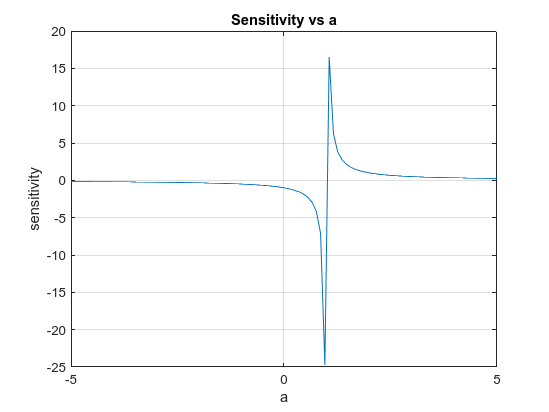


% Plot the expression for a range of a from 0 to 100
plot(avals, subsea)

% Add labels and title
xlabel('a')
ylabel('sensitivity')
title('Sensitivity vs a')
grid on

clear;
syms s

G1s = (s+4) / ((s+3)*(s+7))

$$G1s = \frac{s+4}{\left(s+3\right)\,\left(s+7\right)}$$

Hs = 1/40

Hs = 0.0250


G1s = G1s * 10 * 20

$$G1s = \frac{200\,\left(s+4\right)}{\left(s+3\right)\,\left(s+7\right)}$$


Gs= simplify(G1s/(1+G1s*Hs-G1s))

$$Gs = -\frac{200\,s+800}{-s^{2}+185\,s+759}$$


Kp = subs(Gs,s,0)

$$Kp = -\frac{800}{759}$$

disp(vpa(Kp));

$$-1.0540184453227931488801054018445$$

estep = 1/(1+Kp)

$$estep = -\frac{759}{41}$$

disp(vpa(estep));

$$-18.51219512195121951219512195122$$

 
Kv = subs(s*Gs,s,0)

$$Kv = 0$$

eramp = 1/Kv

$$eramp = \infty$$


Ka = subs(s^2*Gs,s,0)

$$Ka = 0$$

eparab = 1/Ka

$$eparab = \infty$$



Rs = 1/s

$$Rs = \frac{1}{s}$$

Es =  simplify (Rs / (1+Gs))

$$Es = -\frac{-s^{2}+185\,s+759}{s\,\left(s^{2}+15\,s+41\right)}$$


limEs = s*Es

$$limEs = -\frac{-s^{2}+185\,s+759}{s^{2}+15\,s+41}$$


limEs = simplify(subs(limEs,s,0))

$$limEs = -\frac{759}{41}$$